## Projekt HA1 MdR

clear
clc
close all

Definition der Variablen:

global m l k g k_reg M_0
m = 1;
l = 25;
k = 10;
g = 9.81;

phi_0   = 105;
M_0     = m*g*l*sind(phi_0)

M_0 = 236.8933

A = [0,1; -g/l*cosd(phi_0), -k/(l*m)];

q   = (g/l)*cosd(phi_0)

q = -0.1016

p   = k/(l*m)

p = 0.4000

1/(l^2)

ans = 0.0016

w_0     = sqrt(0.2^2+0.248^2)

w_0 = 0.3186

D = -(0.2/w_0)

D = -0.6278

D = 0.7;
sigma = -p/2;
omega = -sqrt((-sigma/D)^2 -sigma^2)

omega = -0.2040

k_reg = l^2*m*((0.2)^2-g/l*cosd(phi_0)+0.204^2)

k_reg = 114.4854

A_k = [0,1; -g/l*cos(phi_0)-k_reg/(l^2*k), -k/(l*m)];

## Aufgabe 7

### $\varphi \;$bei dt = 0.2 mit dem Eulerverfahren

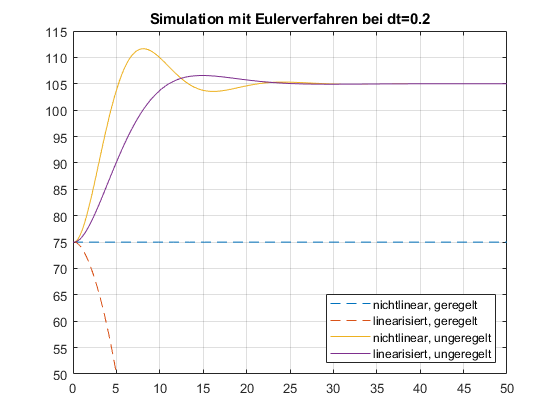

nichtlin_nichtreg_euler(k,l,m,g,k_reg,M_0,0.2)
lin_nichtreg_euler(k,l,m,g,k_reg,M_0,0.2)
nichtlin_reg_euler(k,l,m,g,k_reg,M_0,0.2)
lin_reg_euler(k,l,m,g,k_reg,M_0,0.2)
title("Simulation mit Eulerverfahren bei dt=0.2")
ylim([50 115])
xlim([0 50])
yticks(50:5:115)
legend("nichtlinear, geregelt", "linearisiert, geregelt", "nichtlinear, ungeregelt","linearisiert, ungeregelt","Location","southeast")
hold off

## Aufgabe 8

## phi mit eulerverfahren:

figure("name","phi, euler")
set(gcf,"Visible","on")
subplot(2,3,1)
lin_reg_euler(k,l,m,g,k_reg,M_0,0.1)
ylim([50 150])
hold off
subplot(2,3,2)
lin_reg_euler(k,l,m,g,k_reg,M_0,4)
ylim([50 150])
hold off
subplot(2,3,3)
lin_reg_euler(k,l,m,g,k_reg,M_0,8)
ylim([50 150])
hold off

### phi mit RK4

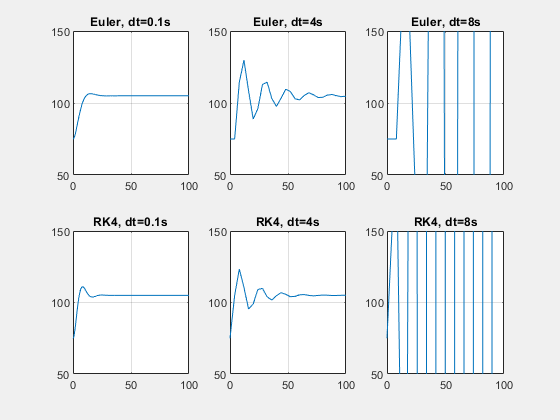

subplot(2,3,4)
lin_reg_ruku(k,l,m,g,k_reg,M_0,0.1)
ylim([50 150])
hold off
subplot(2,3,5)
lin_reg_ruku(k,l,m,g,k_reg,M_0,4)
ylim([50 150])
hold off
subplot(2,3,6)
lin_reg_ruku(k,l,m,g,k_reg,M_0,8)
ylim([50 150])
hold off